# ED and Eo Calcuations for each month

l = 32;
sigma = 30;
sqm = 112.80;
u = 0.24;
y = 45;

disp("ED AND EO MONTH CALCULATOR")

ED AND EO MONTH CALCULATOR


month_input = input("Please input a month: [1-12] ");
data = SolarChart2(month_input,:);
delta = data.DeclinatioNdeg;
et = data.EquationOfTimemin;
a = data.A * 3.2;
b = data.B;
c = data.C;
sunrise = data.AvgSunriseAMMT;

ed = dayEDCalc(l, sigma, y, delta, et, a, b, c, sunrise);
eo = u*ed*sqm;

disp(month_input + " MONTH ED: " + ed)

10 MONTH ED: 6653.0774


disp(month_input + " MONTH EO: " + eo)

10 MONTH EO: 180112.1114


# Battery Calcuations

v = 5;
ah = 30; %30

ec = (v*ah)/1000;
el = 0.5 * ec;

els = (36.3 * 0.6)*(1 + (0.5+0.2)/(100));
vs = v * els;
ecs = els/v;
ahs = (ecs)/(vs)*1000;

nbs = vs/v;
nbp = ahs/ah;

disp("Batteries needed for target month: " + nbp)

Batteries needed for target month: 1.3333


## Eo Graph

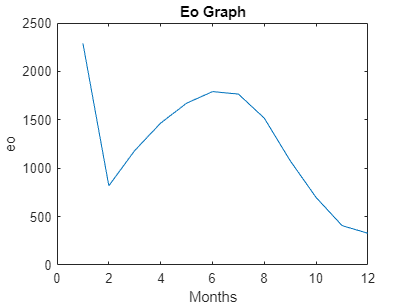

x = 1:12;
y = 1:12;
for i = 1:12
    month = SolarChart2(i,:);
    a = dayEDCalc(l, sigma, y, month.DeclinatioNdeg, month.EquationOfTimemin, month.A, month.B, month.C, month.AvgSunriseAMMT);
    y(1,i) = a(1,1);
end

plot(x,y)
xlabel('Months')
ylabel('eo')
title('Eo Graph')

## ADL Graph

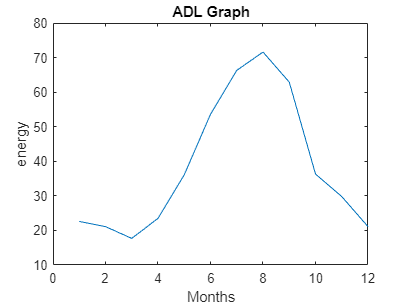

y = [22.6, 21.1, 17.7, 23.5, 36.1, 53.6, 66.3, 71.6, 62.9, 36.3, 29.8, 21.1];
plot(x,y)
xlabel('Months')
ylabel('energy')
title('ADL Graph')